%EE 354 Homework 4
%Lisa Jacklin
% 9/26/2022

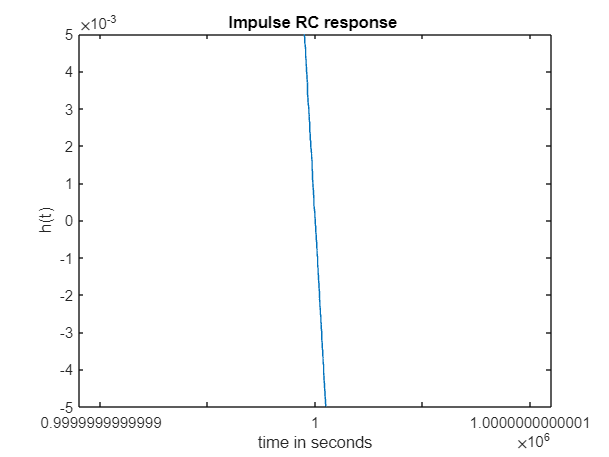

%CE4a. RC-filter in time domain

%values for the format that follows
R = 1000; % 1kohm resistance
C = 1*10^-9; %1uF capacitance
t_start = -5*10^-3; %-5ms start time
t_end = 5*10^-3; %5ms end time
fs = 10000; %10khz sampling frequency
ts = 1/fs; %sampling period

%vectors and equations
t = t_start: ts: t_end;
h = [1/(R*C)] * exp(-t/R*C);

%format given in homework 4 assignment
%must determine what RC_impulse_response is....
%[h,t] = impulse(R,C,t_start, t_end, fs );

plot (h,t);
title('Impulse RC response ')
xlabel('time in seconds')
ylabel('h(t)')


%CE4b. Rectangle Pulse

%additional values not already stated in part a
tau = 2*10^-3; %2ms pulse width
td = 2*10^-3 % pulse delay

td = 0.0020

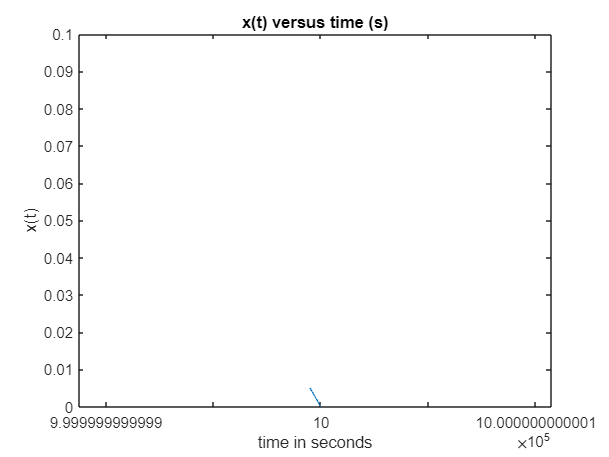


%format given in assignment for part b
% [x,t] = rectangle(tau, td, t_start, t_end, fs);

t = 3*10^-3;
w = 4*10^-3;
 
x = rectpuls(t : w);
ylim ([0 0.1])
%plot(t,x);
title ('x(t) versus time (s)')
xlabel('time in seconds')
ylabel('x(t)')

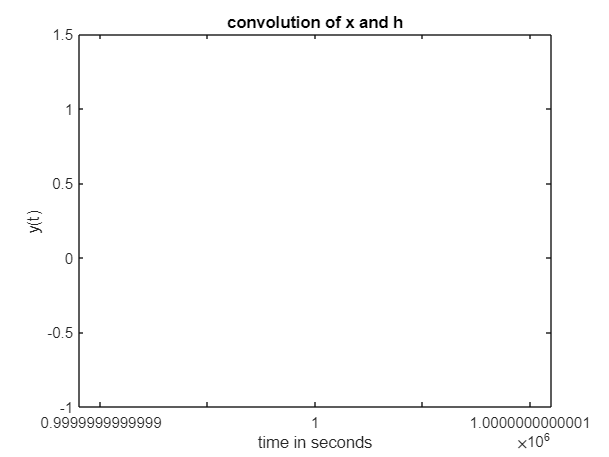


%CE4c. Convolution
%adjusted values for convolution

t_startc = 0;
t_endc = 5*10^-3; %5ms

%note that x and h are the functions created in part a and part b.
y = conv(x, h);
plot (y,t);
title ('convolution of x and h')
xlabel('time in seconds')
ylabel('y(t) ')